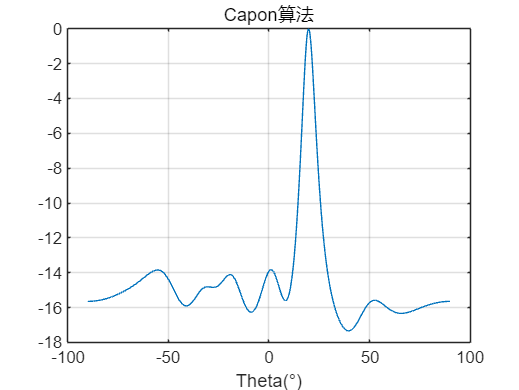

%https://blog.csdn.net/m0_55845774/article/details/143681209
% Capon算法仿真
clc; clear all; close all;

ArrayNum = 10;               %阵面阵元的列数
c = 3e8;             %光速                                     
target_theta = [0,20]; %波达方向
target_num = length(target_theta); 

% Jamming_theta = [0, 50];
% Jamming_num = length(Jamming_theta);
Jamming_theta = [];
Jamming_num = length(Jamming_theta);

f0 = 2e9;           %载频
lambda = c/f0;       %波长
d = lambda/2;        %阵元间距
fs = 10e6;            %快时间采样速率（系统带宽）
Ts = 1 / fs;
Du = 0.001;          %脉冲占空比
Tp = 2e-6;  % 脉宽
B = 5e6;
gamma = B / Tp;
N = 100;          % 快拍数
SNR = 60;        % 信噪比
t = 0:Ts:(N-1)*Ts;
%% 回波信号为LFM信号
s = 10^(SNR/20)*rect(t-Tp/2, Tp).*exp(1i*gamma*pi.*t.^2).*exp(1i*2*pi*f0.*t); % LFM信号

%% 生成导向矢量矩阵
theta = [target_theta, Jamming_theta];
A = exp(-1i*2*pi*(0:ArrayNum-1)'*d*sind(theta)/lambda);

%% 生成接收快拍数据
S = (1:length(theta))'* s;
Noise=randn(ArrayNum, N).*exp(1i*2*pi*rand(ArrayNum,N));
X = A * S + Noise;

%% 求x的相关矩阵逆
Rxx = (1/N).*X * X';
Rxx_inv = inv(Rxx);

Theta = -90:0.1:90;
a_omega = exp(-1i*2*pi*(0:ArrayNum-1)'*d*sind(Theta)/lambda);

P_Capon = abs(diag(1./(a_omega'*Rxx_inv*a_omega)));
%music = abs(diag(1./(a_omega'*(Un*Un')*a_omega)));
P_Capon = 10*log(P_Capon/max(P_Capon));
figure;
plot(Theta, P_Capon);
title('Capon算法');
xlabel('Theta(°)');
grid on;

function y = rect(t, Tp)
    y = double((t >= -Tp/2) & (t < Tp/2));
end